% Project1 - Photogrammetry Calculations

% reading the data from the csv file
data = readtable("gcp_with_types.csv")

data = 42×9 table
       Name        Easting       Northing     El_Height    Latitude    Longitude    E_bin    N_bin      Type   
    __________    __________    __________    _________    ________    _________    _____    _____    _________

    {'pnt001'}    5.6939e+05    4.0269e+06       1490       36.385      51.774        0        2      {'GCP'  }
    {'pnt002'}    5.6956e+05    4.0268e+06       1496       36.384      51.776        0        2      {'CHECK'}
    {'pnt003'}     5.697e+05    4.0267e+06     1501.6       36.383      51.777        0        2      {'GCP'  }
    {'pnt004'}    5.6986e+05    4.0266e+06     1506.7       36.382      51.779        1        2      {'GCP'  }
   


% deriving the needed columns 
x = data.Easting;
y = data.Northing;
X = data.Longitude;
Y = data.Latitude;
type = data.Type;

% initializing arrays & the model by asking the user
chosenModel = string(input("Choose a model:\n", "s"));
disp("**********************************************")

**********************************************


chosenModel 

chosenModel = "polynomial"

xcapGcp = 1.0e-04 *

         0
         0
    0.2405
    0.0000
   -0.0000
    0.0000
         0
         0
    0.0907
   -0.0000


vcapGcp = 1.0e-06 *

    0.0707
    0.0046
    0.1656
    0.0046
    0.0861
    0.0006
   -0.0564
   -0.0029
   -0.0464
   -0.0044


XcapGcp =    51.7737
   51.7771
   51.7789
   51.7825
   51.7856
   51.7875
   51.7908
   51.7930
   51.7883
   51.7912


YcapGcp =    36.3851
   36.3827
   36.3818
   36.3802
   36.3793
   36.3780
   36.3759
   36.3746
   36.3787
   36.3777


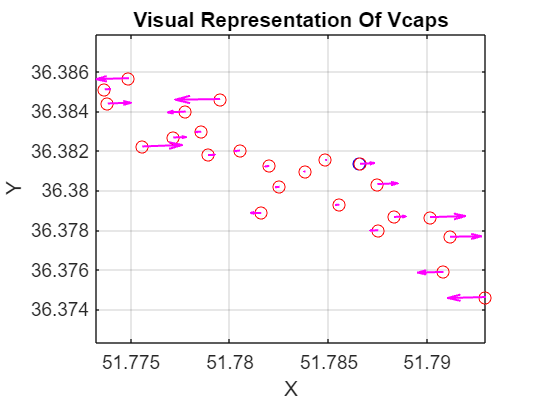

number of GCP points:


    24



number of check points:


    10



RMSEX = 3.0152e-07

RMSEY = 2.0076e-08

RMSEtotal = 3.0219e-07


switch lower(chosenModel)
    case "conformal"
        [nGcp, nCheck] = valueCollector();
        [gcpx, gcpy, checkpx, checkpy, adjGcpX, adjGcpY, adjCheckX, adjCheckY] = gcpCheckProvider(nGcp, nCheck, x, y, X, Y, type);
        if nGcp < 2
            error("Conformal model requires at least 2 GCPs!");
        end
        [xcapGcp, vcapGcp, XcapGcp, YcapGcp] = conformal(gcpx, gcpy, adjGcpX, adjGcpY, nGcp)
        plot(adjGcpX, adjGcpY, "bo")
        hold on;
        plot(XcapGcp, YcapGcp, "ro")
        hold on;
        plotVcapsGcp(adjGcpX, adjGcpY, XcapGcp, YcapGcp)
        disp("number of GCP points:")
        disp(nGcp)
        disp("number of check points:")
        disp(nCheck)
        [RMSEX, RMSEY, RMSEtotal] = rmseCalculator(chosenModel, checkpx, checkpy, adjCheckX, adjCheckY, xcapGcp, nCheck)

    case "affine"
        [nGcp, nCheck] = valueCollector();
        [gcpx, gcpy, checkpx, checkpy, adjGcpX, adjGcpY, adjCheckX, adjCheckY] = gcpCheckProvider(nGcp, nCheck, x, y, X, Y, type);
        if nGcp < 3
            error("Affine model requires at least 3 GCPs!");
        end
        [xcapGcp, vcapGcp, XcapGcp, YcapGcp] = affine(gcpx, gcpy, adjGcpX, adjGcpY, nGcp)
        plot(adjGcpX, adjGcpY, "bo")
        hold on;
        plot(XcapGcp, YcapGcp, "ro")
        hold on;
        plotVcapsGcp(adjGcpX, adjGcpY, XcapGcp, YcapGcp)
        disp("number of GCP points:")
        disp(nGcp)
        disp("number of check points:")
        disp(nCheck)
        [RMSEX, RMSEY, RMSEtotal] = rmseCalculator(chosenModel, checkpx, checkpy, adjCheckX, adjCheckY, xcapGcp, nCheck)

    case "projective"
        [nGcp, nCheck] = valueCollector();
        [gcpx, gcpy, checkpx, checkpy, adjGcpX, adjGcpY, adjCheckX, adjCheckY] = gcpCheckProvider(nGcp, nCheck, x, y, X, Y, type);
        if nGcp < 4
            error("Projective model requires at least 4 GCPs!");
        end
        [xcapGcp, vcapGcp, XcapGcp, YcapGcp] = projective(gcpx, gcpy, adjGcpX, adjGcpY, nGcp)
        plot(adjGcpX, adjGcpY, "bo")
        hold on;
        plot(XcapGcp, YcapGcp, "ro")
        hold on;
        plotVcapsGcp(adjGcpX, adjGcpY, XcapGcp, YcapGcp)
        disp("number of GCP points:")
        disp(nGcp)
        disp("number of check points:")
        disp(nCheck)
        [RMSEX, RMSEY, RMSEtotal] = rmseCalculator(chosenModel, checkpx, checkpy, adjCheckX, adjCheckY, xcapGcp, nCheck)

    case "polynomial"
        [nGcp, nCheck] = valueCollector();
        [gcpx, gcpy, checkpx, checkpy, adjGcpX, adjGcpY, adjCheckX, adjCheckY] = gcpCheckProvider(nGcp, nCheck, x, y, X, Y, type);
        if nGcp < 6
            error("Polynomial (2nd order) requires at least 6 GCPs!");
        end
        [xcapGcp, vcapGcp, XcapGcp, YcapGcp] = polynomial(gcpx, gcpy, adjGcpX, adjGcpY, nGcp)
        plot(adjGcpX, adjGcpY, "bo")
        hold on;
        plot(XcapGcp, YcapGcp, "ro")
        hold on;
        plotVcapsGcp(adjGcpX, adjGcpY, XcapGcp, YcapGcp)
        disp("number of GCP points:")
        disp(nGcp)
        disp("number of check points:")
        disp(nCheck)
        [RMSEX, RMSEY, RMSEtotal] = rmseCalculator(chosenModel, checkpx, checkpy, adjCheckX, adjCheckY, xcapGcp, nCheck)

    otherwise
        disp("Error! Invalid model name!");
end

% functions:

function [nGcp, nCheck] = valueCollector() % F1: getting the number of gcps & check points
    nGcp = input("Enter the number of ground control points:\n");
    while nGcp>30 || nGcp<0
        disp("Error! Invalid number!");
        nGcp = input("Enter the number of ground control points:\n");
    end

    nCheck = input("Enter the number of check points:\n");
    while nCheck>30 || nCheck<0
        disp("Error! Invalid number!");
        nCheck = input("Enter the number of check points:\n");
    end
end

% F2: deriving the arrays (check points & gcps & their corresponding points
% on the ground
function [gcpx, gcpy, checkpx, checkpy, adjGcpX, adjGcpY, adjCheckX, adjCheckY] = gcpCheckProvider(nGcp, nCheck, x, y, X, Y, type)
    gcpx = [];
    gcpy = [];
    adjGcpX = [];
    adjGcpY = [];
    checkpx = [];
    checkpy = [];
    adjCheckX = [];
    adjCheckY = [];

    for i = 1:length(type)
        if strcmp(type{i}, 'GCP')
            gcpx(end+1,1) = x(i);
            gcpy(end+1,1) = y(i);
            adjGcpX(end+1,1) = X(i);
            adjGcpY(end+1,1) = Y(i);
            if length(gcpx) == nGcp
                break;
            end
        end
    end

    for i = 1:length(type)
        if strcmp(type{i}, 'CHECK')
            checkpx(end+1,1) = x(i);
            checkpy(end+1,1) = y(i);
            adjCheckX(end+1,1) = X(i);
            adjCheckY(end+1,1) = Y(i);
            if length(checkpx) == nCheck
                break;
            end
        end
    end
end

% F3: deriving the parameters for conformal model using L.S
function [xcap, vcap, Xcap, Ycap] = conformal(x, y, X, Y, nGcp)
    A = zeros(nGcp * 2, 4);
    for i = 1:nGcp
        A(2*i-1, :) = [x(i), y(i), 1, 0];
        A(2*i, :)   = [y(i), -x(i), 0, 1];
    end

    L0 = zeros(nGcp * 2, 1);
    for i = 1:nGcp
        L0(2*i-1) = X(i);
        L0(2*i)   = Y(i);
    end

    xcap = inv((transpose(A) * A)) * (transpose(A) * L0);
    % xcap = A \ L0

    vcap = (A * xcap) - L0;
    Lcap = A * xcap;

    Xcap = zeros(nGcp, 1);
    Ycap = zeros(nGcp, 1);
    for i = 1:nGcp
        Xcap(i) = Lcap(2*i-1);
        Ycap(i) = Lcap(2*i);
    end
end

% F4: deriving the parameters for affine model using L.S
function [xcap, vcap, Xcap, Ycap] = affine(x, y, X, Y, nGcp)
    A = zeros(nGcp * 2, 6);
    for i = 1:nGcp
        A(2*i-1, :) = [x(i), y(i), 1, 0, 0, 0];
        A(2*i, :)   = [0, 0, 0, x(i), y(i), 1];
    end

    L0 = zeros(nGcp * 2, 1);
    for i = 1:nGcp
        L0(2*i-1) = X(i);
        L0(2*i)   = Y(i);
    end
    % using this one cause the matrix got singular & badly scaled 
    xcap = A \ L0;
    % xcap = inv((transpose(A) * A)) * (transpose(A) * L0)
    vcap = (A * xcap) - L0;
    Lcap = A * xcap;

    Xcap = zeros(nGcp, 1);
    Ycap = zeros(nGcp, 1);
    for i = 1:nGcp
        Xcap(i) = Lcap(2*i-1);
        Ycap(i) = Lcap(2*i);
    end
end

% F5: deriving the parameters for projective model using L.S
function [xcap, vcap, Xcap, Ycap] = projective(x, y, X, Y, nGcp)
    A = zeros(nGcp * 2, 8);
    for i = 1:nGcp
        A(2*i-1, :) = [x(i), y(i), 1, 0, 0, 0, -x(i)*X(i), -y(i)*X(i)];
        A(2*i, :)   = [0, 0, 0, x(i), y(i), 1, -x(i)*Y(i), -y(i)*Y(i)];
    end

    L0 = zeros(nGcp * 2, 1);
    for i = 1:nGcp
        L0(2*i-1) = X(i);
        L0(2*i)   = Y(i);
    end
    % using this one cause the matrix got singular & badly scaled 
    xcap = A \ L0;
    % xcap = inv((transpose(A) * A)) * (transpose(A) * L0)
    vcap = (A * xcap) - L0;
    Lcap = A * xcap;

    Xcap = zeros(nGcp, 1);
    Ycap = zeros(nGcp, 1);
    for i = 1:nGcp
        Xcap(i) = Lcap(2*i-1);
        Ycap(i) = Lcap(2*i);
    end
end

% F6: deriving the parameters for polynomial (order 2) model using L.S
function [xcap, vcap, Xcap, Ycap] = polynomial(x, y, X, Y, nGcp)
    A = zeros(nGcp * 2, 12);
    for i = 1:nGcp
        A(2*i-1, :) = [1, x(i), y(i), x(i)^2, y(i)^2, x(i)*y(i), 0, 0, 0, 0, 0, 0];
        A(2*i, :)   = [0, 0, 0, 0, 0, 0, 1, x(i), y(i), x(i)^2, y(i)^2, x(i)*y(i)];
    end

    L0 = zeros(nGcp * 2, 1);
    for i = 1:nGcp
        L0(2*i-1) = X(i);
        L0(2*i)   = Y(i);
    end
    % using this one cause the matrix got singular & badly scaled 
    xcap = A \ L0;
    % xcap = inv((transpose(A) * A)) * (transpose(A) * L0)
    vcap = (A * xcap) - L0;
    Lcap = A * xcap;

    Xcap = zeros(nGcp, 1);
    Ycap = zeros(nGcp, 1);
    for i = 1:nGcp
        Xcap(i) = Lcap(2*i-1);
        Ycap(i) = Lcap(2*i);
    end
end

% F7: plotting the residuals for GCPs
function plotVcapsGcp(x1, y1, x2, y2)
    xDirection = x2 - x1;   
    yDirection = y2 - y1;   
    % the 0.5 means that the vectors are scaled for better visualization
    quiver(x1, y1, xDirection, yDirection, 0.5, 'm', 'LineWidth', 1);
    axis equal
    grid on
    xlabel('X')
    ylabel('Y')
    title('Visual Representation Of Vcaps')
end

% F9: calculating the RMSE of the model using the derived parameters & the
% check points
function [RMSEX, RMSEY, RMSEtotal] = rmseCalculator(chosenModel, x, y, X, Y, xcap, nCheck)
    if chosenModel == "conformal"
        A = zeros(nCheck * 2, 4);
        for i = 1:nCheck
            A(2*i-1, :) = [x(i), y(i), 1, 0];
            A(2*i, :)   = [y(i), -x(i), 0, 1];
        end
    elseif chosenModel == "affine"
        A = zeros(nCheck * 2, 6);
        for i = 1:nCheck
            A(2*i-1, :) = [x(i), y(i), 1, 0, 0, 0];
            A(2*i, :)   = [0, 0, 0, x(i), y(i), 1];
        end
    elseif chosenModel == "projective"
        A = zeros(nCheck * 2, 8);
        for i = 1:nCheck
            A(2*i-1, :) = [x(i), y(i), 1, 0, 0, 0, -x(i)*X(i), -y(i)*X(i)];
            A(2*i, :)   = [0, 0, 0, x(i), y(i), 1, -x(i)*Y(i), -y(i)*Y(i)];
        end
    elseif chosenModel == "polynomial"
        A = zeros(nCheck * 2, 12);
        for i = 1:nCheck
            A(2*i-1, :) = [1, x(i), y(i), x(i)^2, y(i)^2, x(i)*y(i), 0, 0, 0, 0, 0, 0];
            A(2*i, :)   = [0, 0, 0, 0, 0, 0, 1, x(i), y(i), x(i)^2, y(i)^2, x(i)*y(i)];
        end
    end

    Lcap = A * xcap;

    Xcap = zeros(nCheck, 1);
    Ycap = zeros(nCheck, 1);

    for i = 1:nCheck
        Xcap(i) = Lcap(2*i-1);
        Ycap(i) = Lcap(2*i);
    end

    RMSEX = rmse(X, Xcap);
    RMSEY = rmse(Y, Ycap);
    RMSEtotal = sqrt(RMSEX^2 + RMSEY^2);
end